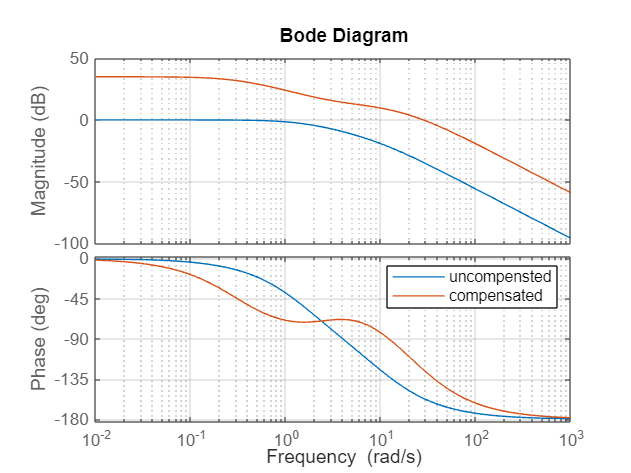

%NAME: WYCLIFFE MACHUKI OKENYE
%REG: EG209/106813/21
%CONTROL ASSIGNMENT

% Case 1: G1(s) = 9/(s^2 + 4 s + 9)
s = tf('s');
G1 = 16/(s^2 + 12*s + 16);%%open loopTf for uncompensated sytem

% Proposed compensators
C_lead = 70*(s+2)/(s+23);%%lead comaparator
C_lag  = (s+3)/(s+0.3);
C_T= C_lead * C_lag;%%lead and lag in cascade
% Closed-loop (unity feedback)
T1 = feedback(C_T * G1, 1);
% bode plot for uncompenated system and compensated system
figure;
bode(G1, C_T*G1); 
legend('uncompensted','compensated');
grid on;

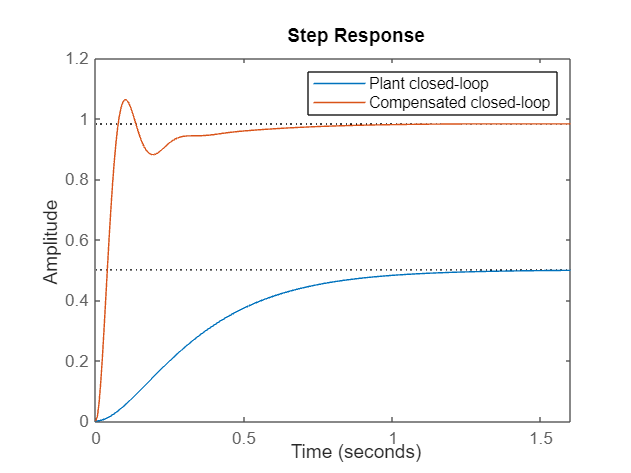

Step info for compensated case 1:


         RiseTime: 0.0504
    TransientTime: 0.5440
     SettlingTime: 0.5440
      SettlingMin: 0.8809
      SettlingMax: 1.0634
        Overshoot: 8.2392
       Undershoot: 0
             Peak: 1.0634
         PeakTime: 0.1013



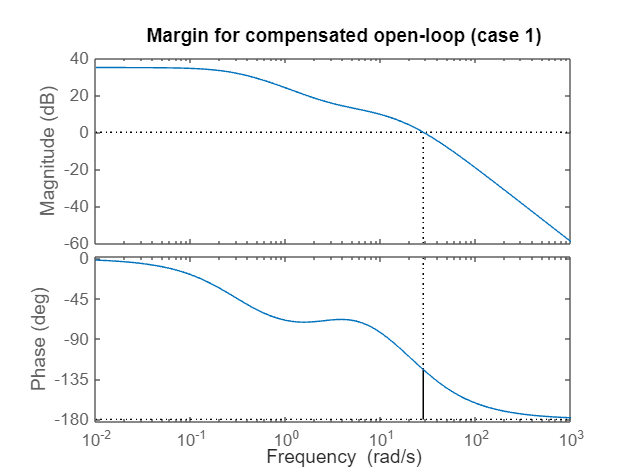

%%step polots for uncompensatedand fully_compensted system
figure; 
step(G1/(1+G1), T1); 
legend('Plant closed-loop','Compensated closed-loop');